# Autoencoder airfoil generator

## Train an autoencoder

unzip('airfoils.zip', 'airfoils');
encoder = train_selig('airfoils', 5, 5, 100, 'MaxEpochs', 10000)

encoder =   Autoencoder with properties:

                 HiddenSize: 5
    EncoderTransferFunction: 'logsig'
             EncoderWeights: [5×10 double]
              EncoderBiases: [5×1 double]
    DecoderTransferFunction: 'logsig'
             DecoderWeights: [10×5 double]
              DecoderBiases: [10×1 double]
         TrainingParameters: [1×1 struct]
                  ScaleData: 1


## Set parameter variables (live reload)

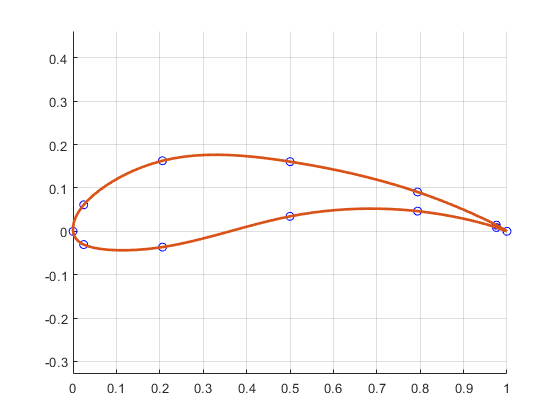

a1 = 0.107;
a2 = 0.107;
a3 = 0.547;
a4 = 0.052;
a5 = 0.125;
ch_xx = chebyshevs(5);
af = (decode(encoder, [a1; a2; a3; a4; a5])/100)';
ex_xx = [ 1 fliplr(ch_xx) 0 ch_xx 1];
ex_yy = [0 af(1:5) 0 af(6:10) 0];
clf
hold on
plot(ex_xx, ex_yy, 'bo');
curve = cscvn([ex_xx;ex_yy]);
fnplt(curve)
hold off
axis equal
grid on

Set all parameters (live reload)

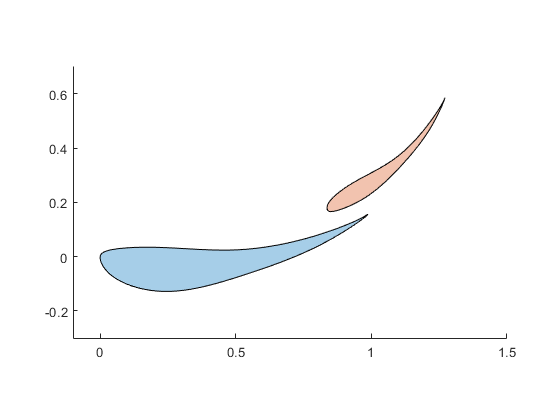

e1_1 = 0.107;
e1_2 = 0.221;
e1_3 = 0.547;
e1_4 = 0.052;
e1_5 = 0.125;
e2_1 = 0.129;
e2_2 = 0.068;
e2_3 = 0.547;
e2_4 = 0.166;
e2_5 = 0;
a1 = 9;
a2 = 44;
x2 = 0.84;
y2 = 0.17;
s2 = 0.6;
el1 = decodeAirfoil(encoder, [e1_1; e1_2; e1_3; e1_4; e1_5], 0.01, ch_xx);
el2 = decodeAirfoil(encoder, [e2_1; e2_2; e2_3; e2_4; e2_5], 0.01, ch_xx);
[e1m, e2m] = twoairfoils(el1, a1, el2, a2, x2, y2, s2);
plot([e1m e2m])
axis equal
xlim([-0.1 1.5])
ylim([-0.3 0.7])